# Week 13

Exercise 2

clear
close all

Part a


R = 100;
C = 10e-6;
L = 2.5;

s = tf('s');
T = 1/(L*C*s^2+R*C*s+1)

T =
 
              1
  -------------------------
  2.5e-05 s^2 + 0.001 s + 1
 
Continuous-time transfer function.



Part b

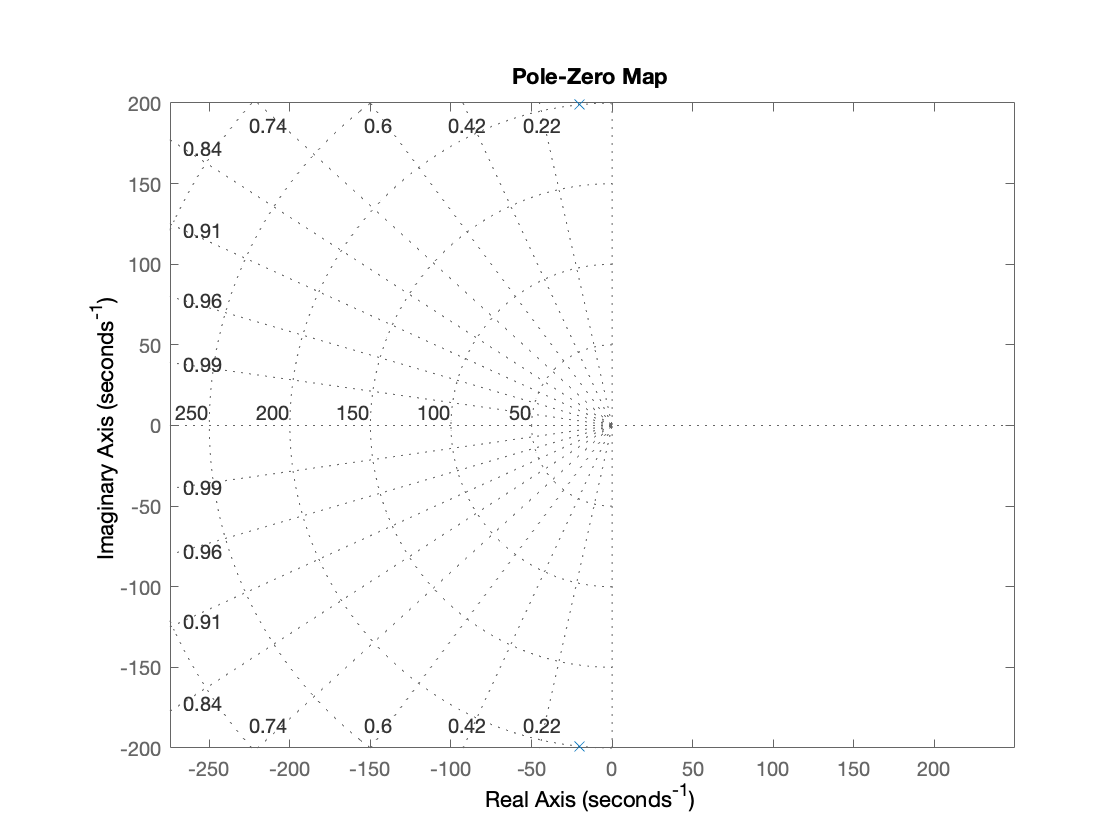


[p,z] = pzmap(T);
pzmap(T)
axis equal
grid on

Part c

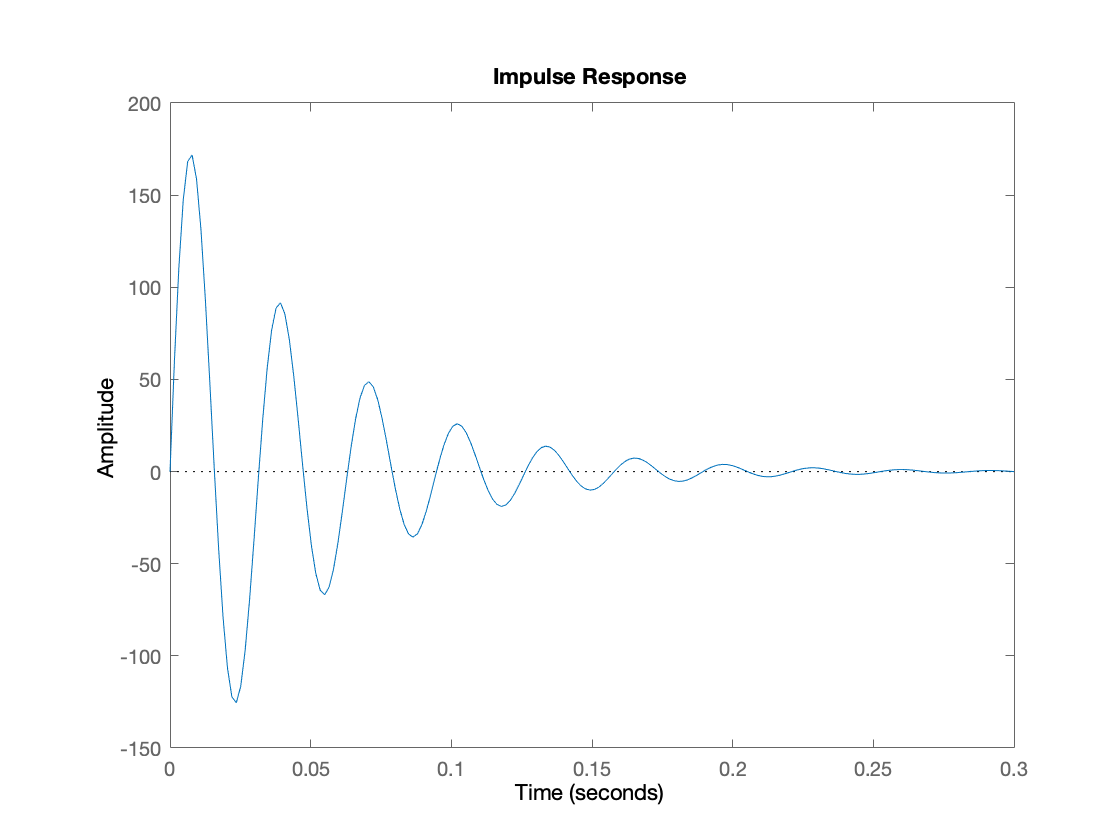


impulse(T)

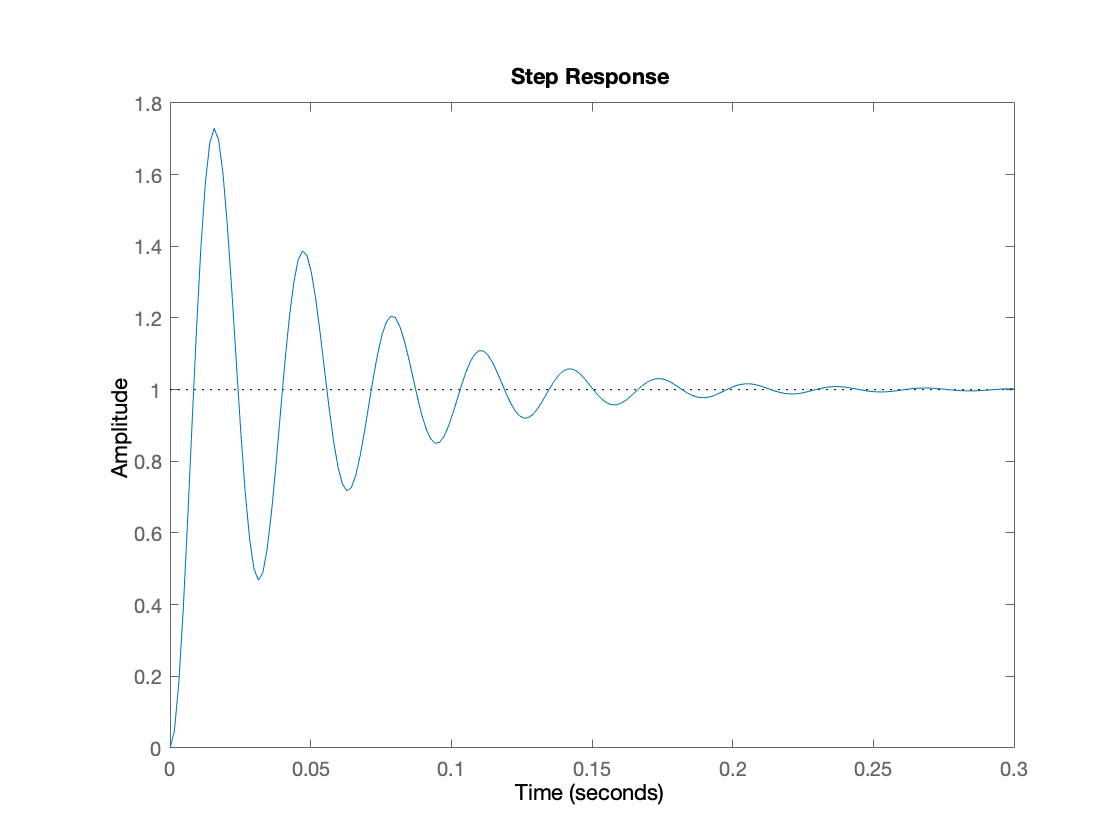

step(T)

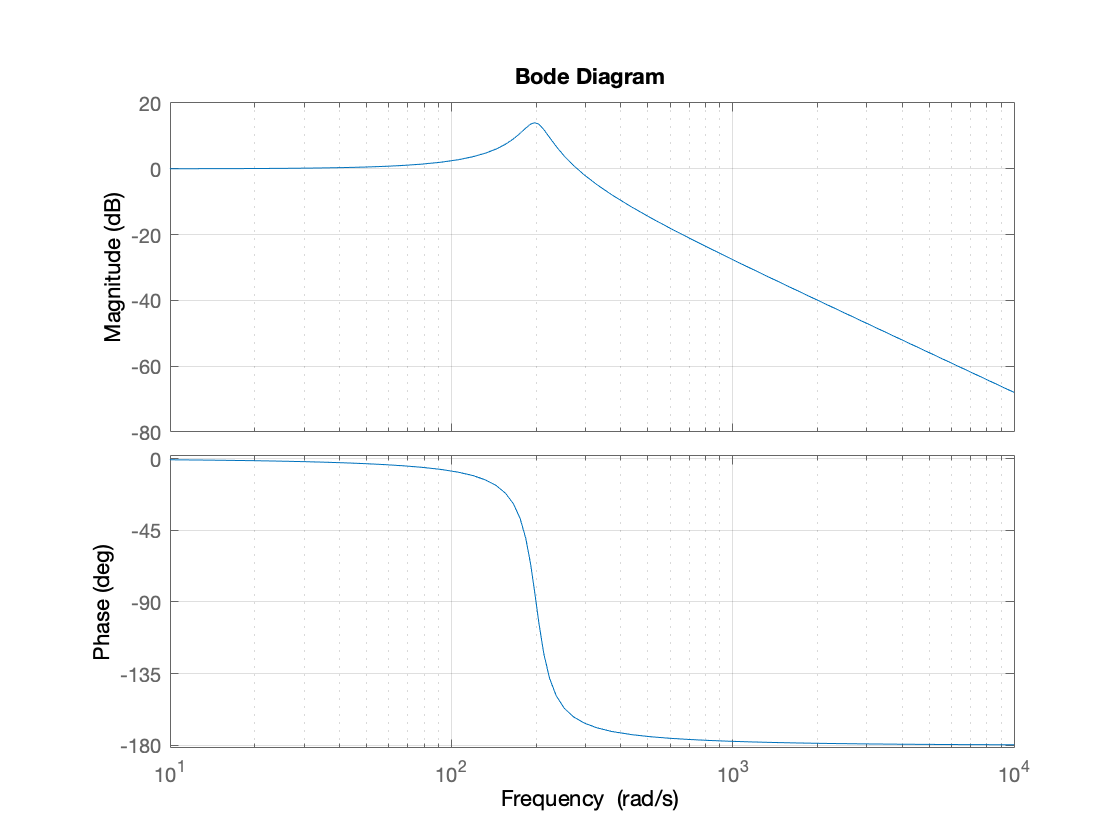

bode(T)
grid on

Part d


omega = 1/sqrt(L*C)

omega = 200

zeta = R/(2*omega*L)

zeta = 0.1000

[mag,phase] = bode(T,omega)

mag = 5.0000

phase = -90.0000

assert(mag - 1/(2*zeta) < 1e-6)


Part e

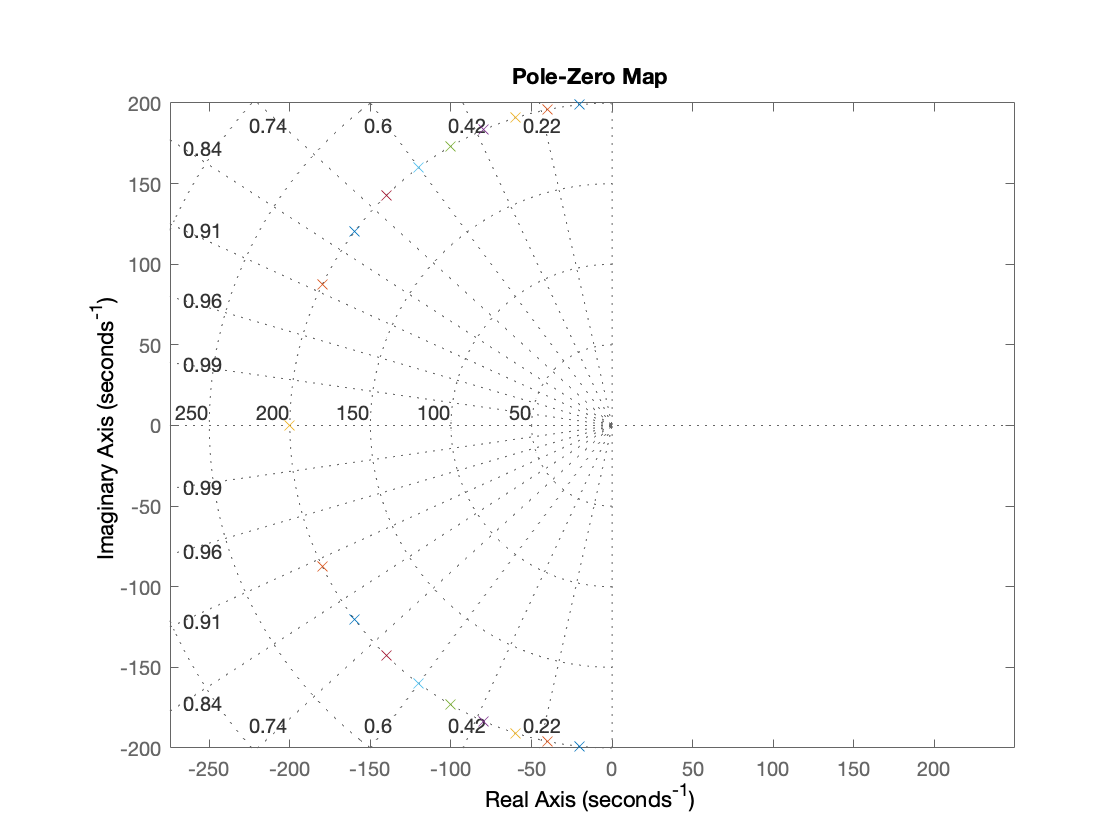


omega = 200;

figure
for zeta = 0.1:0.1:1
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    pzmap(T)
    axis equal
    grid on
    hold on
    pause(0.2)
end

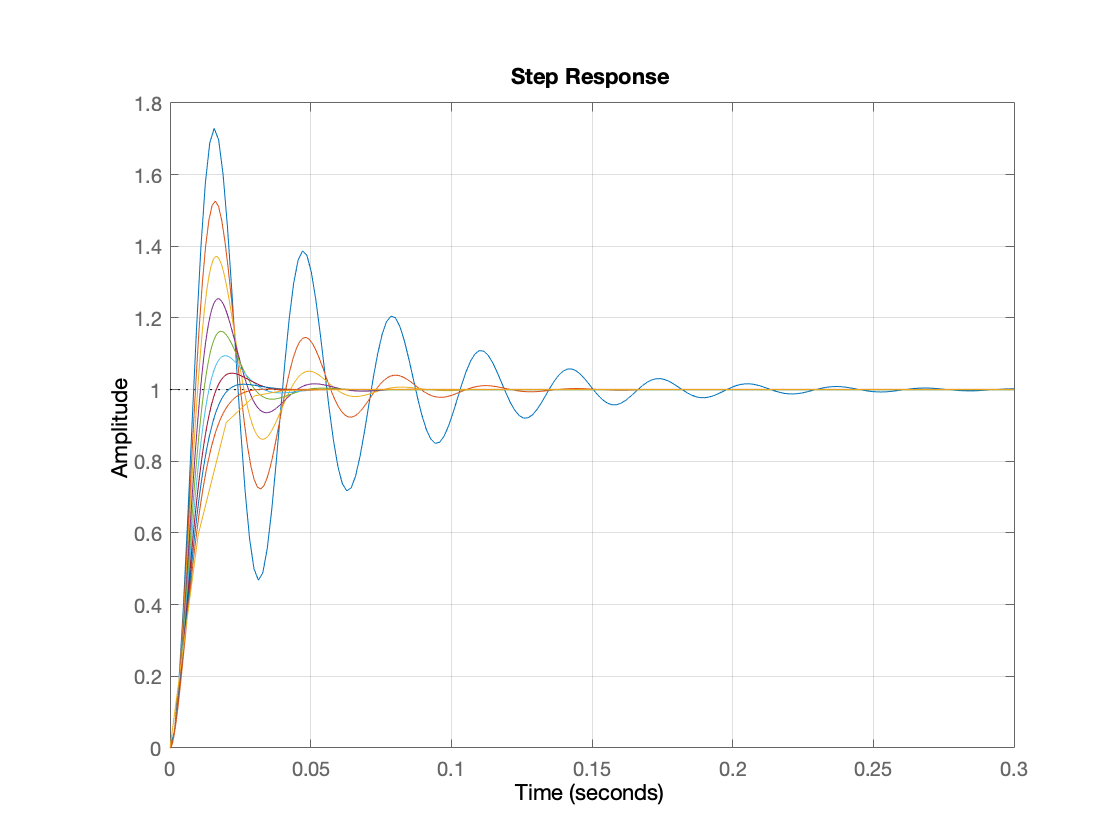


figure
for zeta = 0.1:0.1:1
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    step(T)
    grid on
    hold on
    pause(0.2)
end

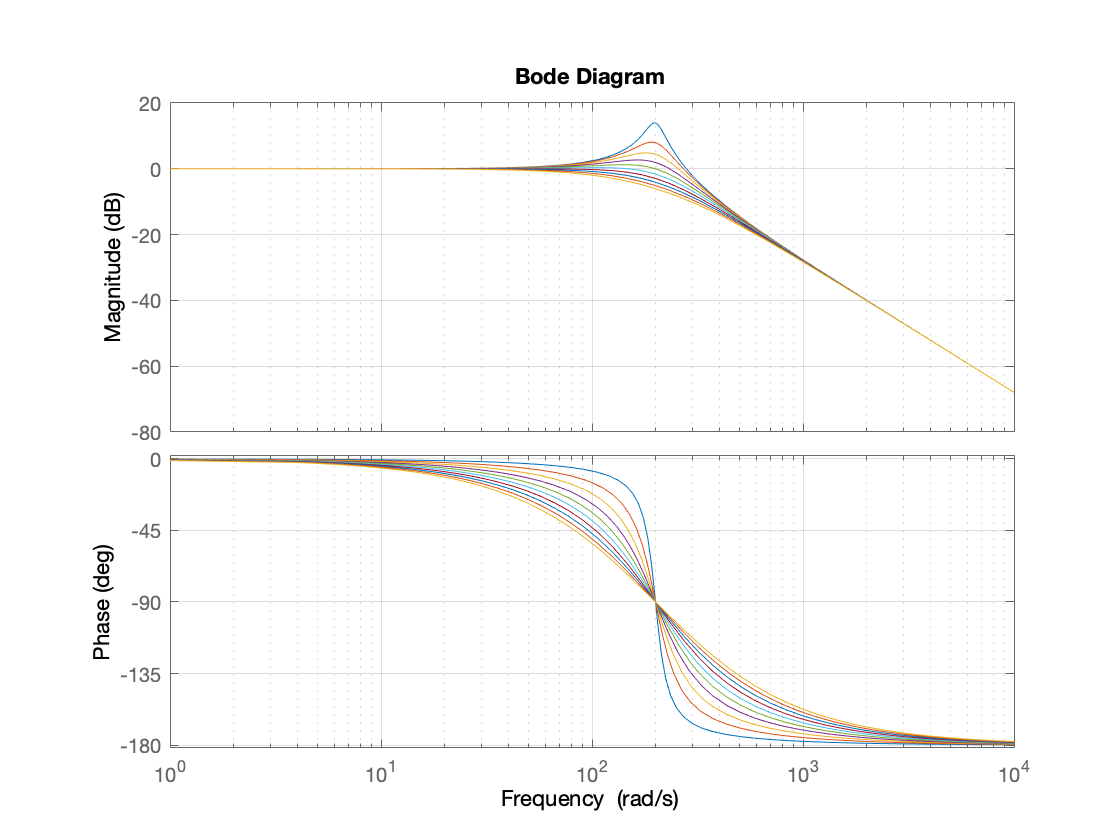


figure
for zeta = 0.1:0.1:1
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    bode(T)
    grid on
    hold on
    pause(0.2)
end

Part f

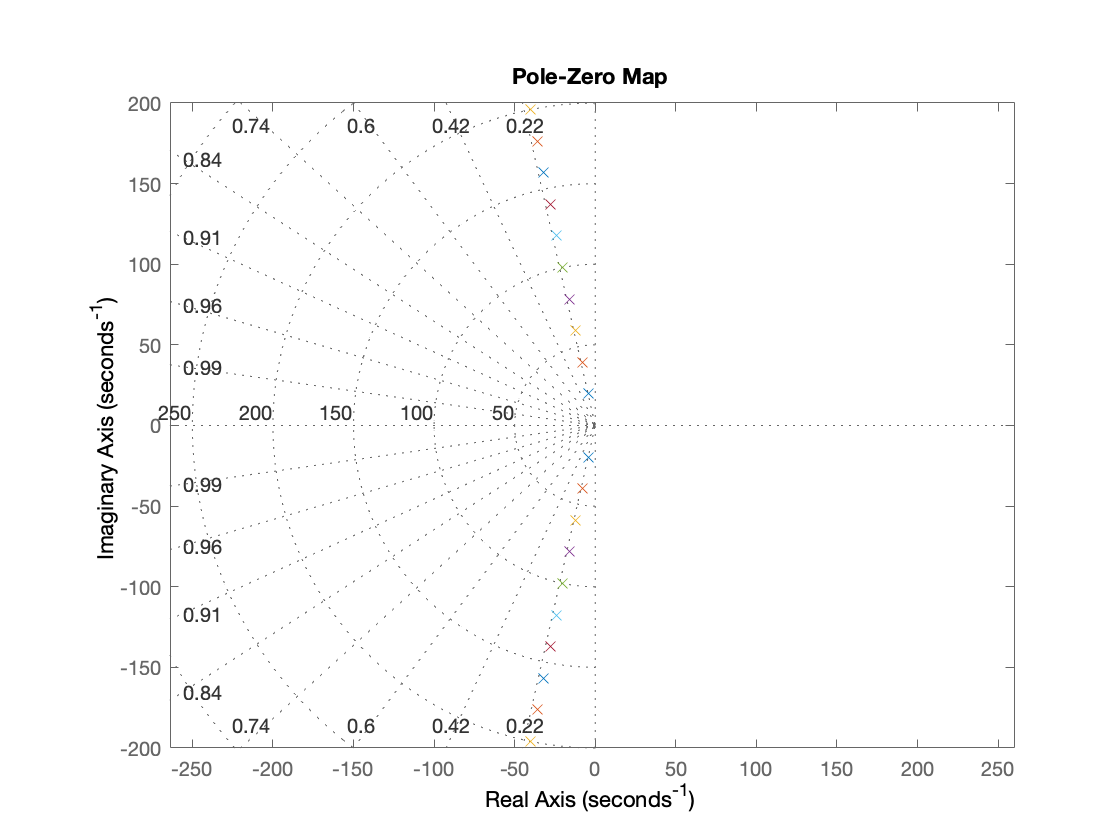


zeta = 0.2;

figure
for omega = 20:20:400
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    pzmap(T)
    axis equal
    grid on
    hold on
    pause(0.2)
end

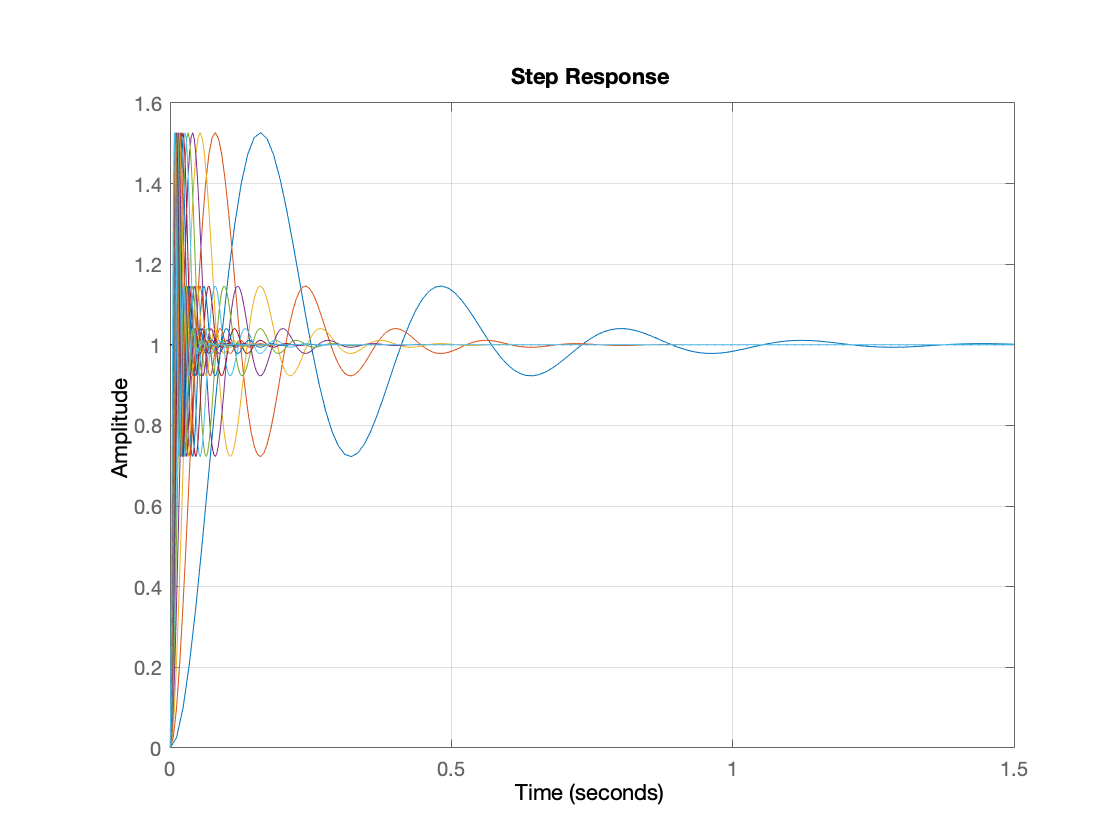


figure
for omega = 20:20:400
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    step(T)
    grid on
    hold on
    pause(0.2)
end

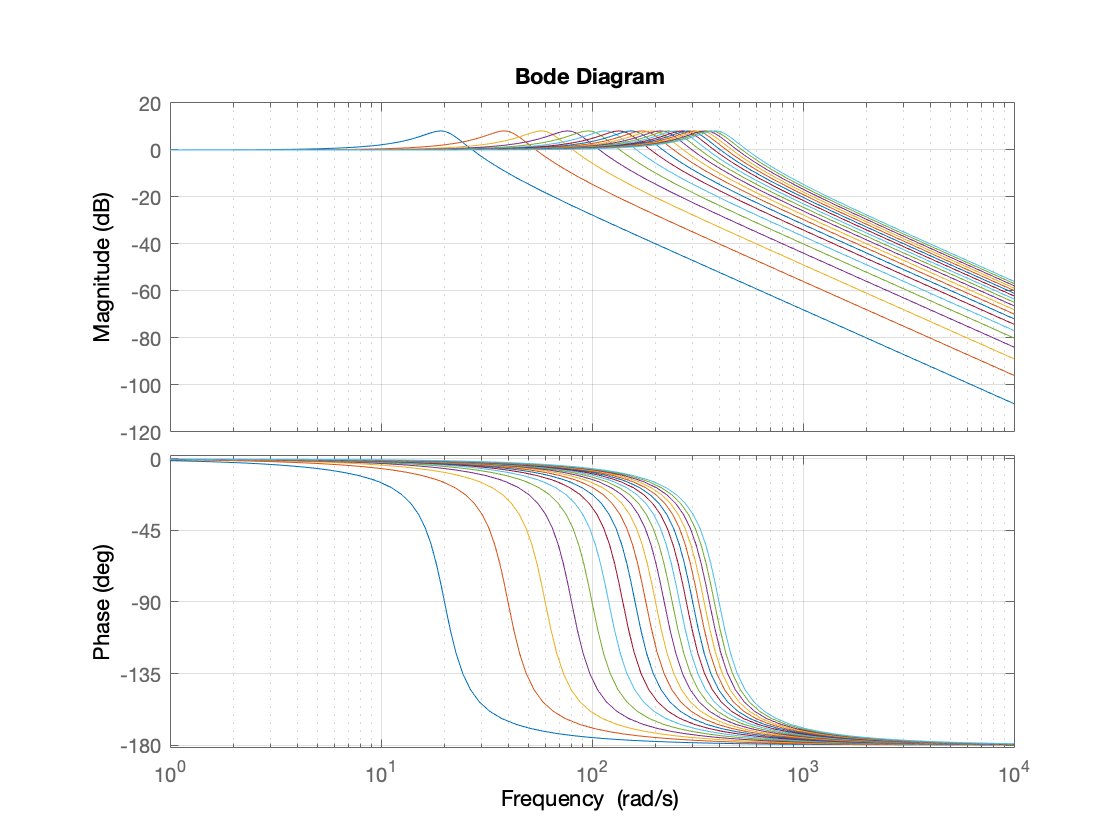


figure
for omega = 20:20:400
    T = omega^2/(s^2+2*zeta*omega*s+omega^2);
    bode(T)
    grid on
    hold on
    pause(0.2)
end